clear all; clc;
% cd(fileparts(which(mfilename)));  % In a .m file uncomment this
cd(fileparts(matlab.desktop.editor.getActiveFilename)); % In a .mlx file uncomment this

# Example: Mass Spring Damper

Develop a Kalman filter to track the state of the typical Mass Spring Damper. We have an external forze. We use an acceleration sensor.

## 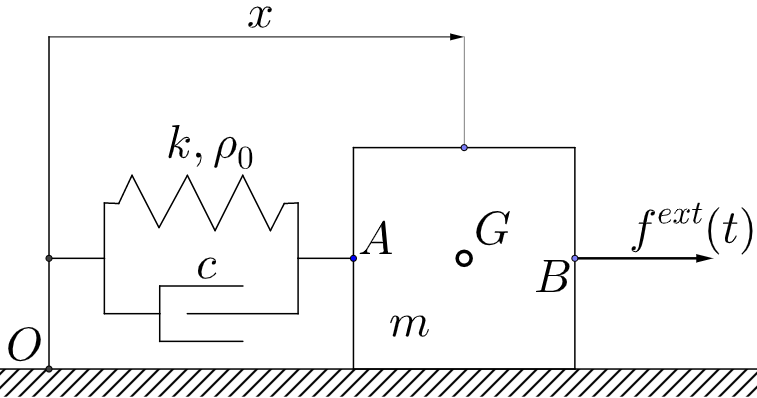

Determine transition process equations & sensor equations, and the required Jacobians.

# Solution:

## This is the first part of the solution: Determine model and sensor equations, and export the required functions for simulation and Kalman filtering.

The derivative w.r.t. time of the state, $\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ It is used to simulate the "true state" $\mathbf{x}^{tr}$.

$\dot{\mathbf{x}}(\mathbf{x},\mathbf{u},t)$ is used to define the discretized model, $\mathbf{x}_{k+1}=\mathbf{f}(\mathbf{x}_{k},\mathbf{u}_k,t_0+k~\Delta t)$ used in the Kalman filter.

$\mathbf{h}$, $\mathbf{z}_{k+1}=\mathbf{h}(\mathbf{x}_{k+1},\mathbf{u}_{k+1},t_0+(k+1)~\Delta t)$, is used to define the "true mesurements" in terms of the "true state" that is contamined with noise to generate noisy measurements.

$\mathbf{f}$ and $\mathbf{h}$ and their Jacobians w.r.t. state, $\mathbf{x}$, and input, $\mathbf{u}$, $\mathbf{f}_\mathbf{x}$, $\mathbf{f}_\mathbf{{u}$, $\mathbf{h}_\mathbf{x}$, $\mathbf{h}_\mathbf{{u}$, must be exported.

***NOTE:**** Even if the system in this example is linear we recover the linear components of the system from the general functions ( *$\mathbf{f}$* and *$\mathbf{h}$*) used in the quasilinerar version of the Kalman filter (Extendend Kalman filter) using this perspective there is no difference between Kalman and Extendend Kalman filter implementation and reasoning.*

## Parameters

syms t x dx ddx m k rho0 c Delta_t f_ext real
param=[m k rho0 c Delta_t]';

Generalized coordinate, velocity and acceleration vectors:

$\mathbf{q}=\left[\begin{array}{c}
x\\
y
\end{array}\right]$,$\dot{\mathbf{q}}=\left[\begin{array}{c}
\dot{x}\\
\dot{y}
\end{array}\right]$and $\ddot{\mathbf{q}}=\left[\begin{array}{c}
\ddot{x}\\
\ddot{y}
\end{array}\right]$

q=[x]';
dq=[dx]';
ddq=[ddx]';

Forces acting on the particle. Inertia & gravity (gravity not defined not required):

$\mathbf{f}^{I}=-m ~\mathbf{a}_{IR}^P=-m ~\ddot{x}~\mathbf{e}_x$, $\mathbf{f}^{g}=-m~g~\mathbf{e}_y$


$$\mathbf{f}^{SD}=-(k ~(x-\rho_0) + c~\dot{x}) ~\mathbf{e}_{x}$$



$$\mathbf{f}^{ext}=f^{ext}~\mathbf{e}_{x}$$


Particle velocity:


$$\mathbf{v}^A=\mathbf{v}^B=\mathbf{v}^G=x~\mathbf{e}_x$$


Virtual power equations:


$$\mathbf{f}^{I}\cdot\frac{\partial~\mathbf{v}^G }{\partial~ \dot{\mathbf{q}}}+\mathbf{f}^{SD}\cdot\frac{\partial~\mathbf{v}^A }{\partial~ \dot{\mathbf{q}}}+\mathbf{f}^{ext} \cdot \frac{\partial~\mathbf{v}^B }{\partial~ \dot{\mathbf{q}}}=\mathbf{0}$$


iF=-m*[ddx,0,0]' %xyz

 
iF =
 
-ddx*m
     0
     0
 


sdF=[-k*(x-rho0),0,0]'+[-c*dx,0,0]' %xyz

 
sdF =
 
k*(rho0 - x) - c*dx
                  0
                  0
 


extF=[f_ext,0,0]' %xyz

 
extF =
 
f_ext
    0
    0
 



V_G=[dx,0,0]' %xyz

 
V_G =
 
dx
 0
 0
 


V_A=V_G %xyz

 
V_A =
 
dx
 0
 0
 


V_B=V_G %xyz

 
V_B =
 
dx
 0
 0
 



Dyn_eq=-((iF'*jacobian(V_G,dq))'+...
   (sdF'*jacobian(V_A,dq))'+...
   (extF'*jacobian(V_B,dq))'); Dyn_eq=simplify(Dyn_eq)

 
Dyn_eq =
 
c*dx - f_ext + ddx*m - k*(rho0 - x)
 


Virtual power dynamic equations structure


$$\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}}~\ddot{\mathbf{q}}-{\mathbf{\delta}}_{\dot{\mathbf{q}}}=\mathbf{0}$$


M_qq=jacobian(Dyn_eq,ddq); M_qq=simplify(M_qq)

 
M_qq =
 
m
 


delta_q=-subs(Dyn_eq,ddq,sym(0)*ddq); delta_q=simplify(delta_q)

 
delta_q =
 
f_ext - c*dx + k*(rho0 - x)
 


Therefore $\ddot{\mathbf{q}}(\mathbf{x},\mathbf{u},t)=\mathbf{M}_{\dot{\mathbf{q}}\dot{\mathbf{q}}} ^{-1}~\mathbf{\delta}_{\dot{\mathbf{q}}}$

ddq_func=inv(M_qq)*delta_q; ddq_func=simplify(ddq_func)

 
ddq_func =
 
(f_ext - c*dx + k*(rho0 - x))/m
 


To write the differential equation into first order form, the state space vector is defined as $\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\  \dot{\mathbf{q}}\end{array} \right]$.

x_=[q;dq]

 
x_ =
 
 x
dx
 


$\mathbf{u}$ is  defined as $f^{ext}$.

u=sym([f_ext])

 
u =
 
f_ext
 



$$\dot{\mathbf{x}}(\mathbf{x},t)=\left[\begin{array}{c} \dot{\mathbf{q}} \\ \ddot{\mathbf{q}}(\mathbf{q},\dot{\mathbf{q}},t)\end{array}\right]$$


dstate=[dq;ddq_func]; dstate=simplify(dstate)

 
dstate =
 
                             dx
(f_ext - c*dx + k*(rho0 - x))/m
 


$\dot{\mathbf{x}}_{\mathbf{x}}(\mathbf{x},t)=\frac{\partial~\dot{\mathbf{x}}(\mathbf{x},t)}{\partial ~\mathbf{x}}$, can be usefull if using exponential integration discretization.

dstate_x=jacobian(dstate,x_)

 
dstate_x =
 
[   0,    1]
[-k/m, -c/m]
 


We discretize the differential equation for the state vector, using the trivial Euler dicretization scheme, in order to obtain the discrete state transition function.

f=x_+dstate*Delta_t; f=simplify(f) %x_k+1=f(x_k)

 
f =
 
                                x + Delta_t*dx
dx + (Delta_t*(f_ext - c*dx + k*(rho0 - x)))/m
 



f_x=jacobian(f,x_); f_x=simplify(f_x)

 
f_x =
 
[             1,           Delta_t]
[-(Delta_t*k)/m, 1 - (Delta_t*c)/m]
 


f_u=jacobian(f,u); f_u=simplify(f_u)

 
f_u =
 
        0
Delta_t/m
 


Acceleration sensor in $\mathbf{e}_x$ require defining acceleration in terms of the state $\mathbf{x}$.

h=[ddq_func]; h=simplify(h)

 
h =
 
(f_ext - c*dx + k*(rho0 - x))/m
 


h_x=jacobian(h,x_); h_x=simplify(h_x)

 
h_x =
 
[-k/m, -c/m]
 


h_u=jacobian(h,u); h_u=simplify(h_u)

 
h_u =
 
1/m
 


matlabFunction(f,'file','f','vars',{x_ u t param});
matlabFunction(f_x,'file','f_x','vars',{x_ u t param});
matlabFunction(f_u,'file','f_u','vars',{x_ u t param});
matlabFunction(h,'file','h','vars',{x_ u t param});
matlabFunction(h_x,'file','h_x','vars',{x_ u t param});
matlabFunction(h_u,'file','h_u','vars',{x_ u t param});
matlabFunction(dstate,'file','dstate','vars',{x_ u t param});
matlabFunction(dstate_x,'file','dstate_x','vars',{x_ u t param});